# Pathplanning example

## Make points and make path

Points are in (x,y,z) coordinates. Also include first and second derivitive

This can be in any coordinate system, also with more than 3 dofs.

px = [0 0.5 1 0.5];
py = [0.5 1 0.5 0];
pz = [0 0 0 0];
p = [px;py;pz];


dpx = [0 1 0 -1];
dpy = [1 0 -1 0];
dpz = [0 0 0 0];
dp = [dpx;dpy;dpz];


ddpx = [1 0 -1 0];
ddpy = [0 -1 0 1];
ddpz = [0 0 0 0];
ddp = [ddpx;ddpy;ddpz];

%I call the path h(s), dh = h'(s), ddh = h''(s)
[h,dh,ddh] = PathPlanning(p,dp,ddp);
n = size(p,1); %number of DOFS (index i)
N = size(p,2); %number of line segments (index k)


## Ploting path

Inserts numbers in path (h) to get 3rd order tensor "T_ijk" of points that can be plotted

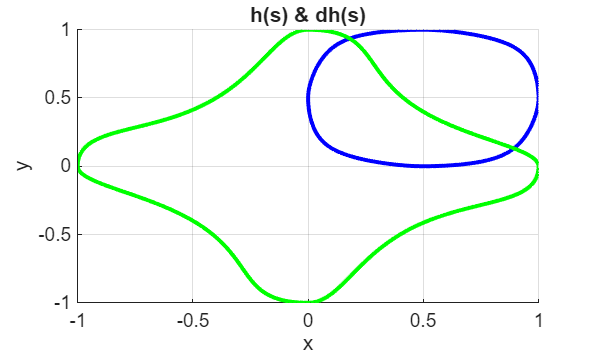

s = 0:0.01:1; %all line segments are parameterized from 0-1 (index j)

h_ = zeros(n,size(p,2),length(s));
dh_ = zeros(n,size(p,2),length(s));

for i = 1:n
    h_n = h{i};
    dh_n = dh{i};
    for k = 1:length(s)
        h_(i,:,k) = h_n(s(k));
        dh_(i,:,k) = dh_n(s(k));
    end
end

%make 3rd order tensor to matrix with [x;y;z] for ploting path
positon = zeros(n,N*length(s));
velocity = zeros(n,N*length(s));
for i = 1:n %Dofs
    tau = 1;
    for j = 1:N %segments
        for k = 1:length(s) %place on segment
            positon(i,tau) = h_(i,j,k);
            velocity(i,tau) = dh_(i,j,k);
            tau = tau+1;
        end
    end
    
end

figure('Name','path')
title('h(s) & dh(s)')
hold on
plot3(positon(1,:),positon(2,:),positon(3,:),'color','b','LineWidth', 2)
plot3(velocity(1,:),velocity(2,:),velocity(3,:),'color','g','LineWidth', 2)
xlabel('x')
ylabel('y')
grid on
hold off

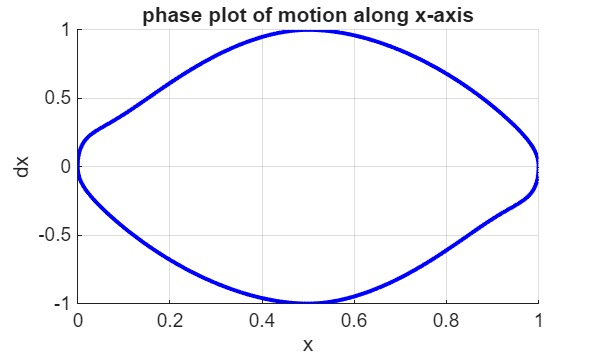


figure('Name','phase portrait x')
title('phase plot of motion along x-axis')
hold on
plot(positon(1,:),velocity(1,:),'color','b','LineWidth', 2);
xlabel('x')
ylabel('dx')
grid on
hold off

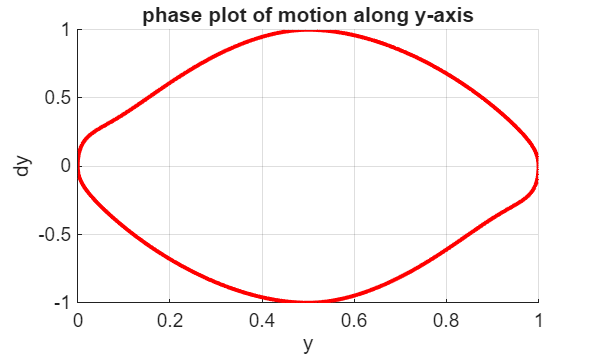

ans =          0    0.5000    1.0000    0.5000
    0.5000    1.0000    0.5000         0
         0         0         0         0


ans =     0.1250    0.8906    0.8750    0.1094
    0.8906    0.8750    0.1094    0.1250
         0         0         0         0


ans =     0.5000    1.0000    0.5000         0
    1.0000    0.5000         0    0.5000
         0         0         0         0


dynamics = function_handle with value:
    @(t,x)f(x,parms)+g(x,u,parms)



figure('Name','phase portrait y')
title('phase plot of motion along y-axis')
hold on
plot(positon(2,:),velocity(2,:),'color','r','LineWidth', 2);
xlabel('y')
ylabel('dy')
grid on
hold off